clc; clear all;
x = [4000 4260 4550 4860];
vx = [280 282 285 286];
ax=2; 
dt=1; 
dx=25; 
dpx=20; 
dpv=5; 
da=25; 
dv=6;

A = [1 dt;0 1];
B = [0.5*dt*dt;dt];
U = [ax];


pred_X=[4000];
pred_V=[280];
measured_X=[4000];
measured_V=[280];
filt_X=[4000];
filt_V=[280];

t=[0 1 2 3]';

R=[da^2 0;0 dv^2];
s0 = [x(1); vx(1)];
cov0 = diag(diag([dpx^2 dpx*dpv; dpx*dpv dpv^2]));
H = eye(2); C = eye(2); I = eye(2);

for i = 2:4
    pred_state = A*s0 + B*U;
    pred_cov = diag(diag(A*cov0*A'));
    kalmanGain = (pred_cov*H)/(H*pred_cov*H' + R);
    obs_0 = [ x(i);vx(i)];
    new_obs = C*obs_0;
    new_state=pred_state + (kalmanGain*(new_obs - H*pred_state));
    cov = (I-kalmanGain*H)*pred_cov;
    pred_X=[pred_X;pred_state(1,1)];
    pred_V=[pred_V;pred_state(2,1)];
    measured_X=[measured_X;x(i)];
    measured_V=[measured_V;vx(i)];
    filt_X=[filt_X;new_state(1,1)];
    filt_V=[filt_V;new_state(2,1)];
    fprintf('t = %d\n', i-1);
    disp('initial observation');
    disp(obs_0);
    disp('new observation');
    disp(new_obs);
    disp('initial process covariance');
    disp(cov0);
    disp('predicted process covariance');
    disp(pred_cov)
    disp(' process covariance');
    disp(cov)
    disp('initial state')
    disp(s0)
    disp('predicted state')
    disp(pred_state)
    disp('state')
    disp(new_state)
    s0=new_state;
    cov0=cov;
end

t = 1


initial observation


        4260
         282



new observation


        4260
         282



initial process covariance


   400     0
     0    25



predicted process covariance


   425     0
     0    25



 process covariance


  252.9762         0
         0   14.7541



initial state


        4000
         280



predicted state


        4281
         282



state


   1.0e+03 *

    4.2725
    0.2820



t = 2


initial observation


        4550
         285



new observation


        4550
         285



initial process covariance


  252.9762         0
         0   14.7541



predicted process covariance


  267.7303         0
         0   14.7541



 process covariance


  187.4378         0
         0   10.4651



initial state


   1.0e+03 *

    4.2725
    0.2820



predicted state


   1.0e+03 *

    4.5555
    0.2840



state


   1.0e+03 *

    4.5539
    0.2843



t = 3


initial observation


        4860
         286



new observation


        4860
         286



initial process covariance


  187.4378         0
         0   10.4651



predicted process covariance


  197.9029         0
         0   10.4651



 process covariance


  150.3085         0
         0    8.1081



initial state


   1.0e+03 *

    4.5539
    0.2843



predicted state


   1.0e+03 *

    4.8391
    0.2863



state


   1.0e+03 *

    4.8442
    0.2862



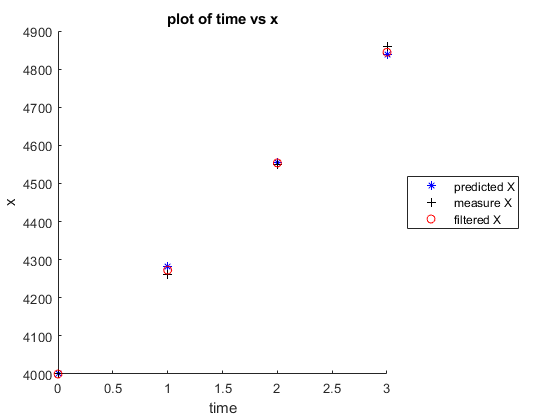


figure(1);
scatter(t,pred_X, 'b', '*');
hold on;
scatter(t,measured_X, 'k', '+');
hold on;
scatter(t,filt_X, 'r', 'o');
title("plot of time vs x")
xlabel('time')
ylabel('x')
legend('predicted X','measure X','filtered X', 'Location', 'eastoutside')
hold off;

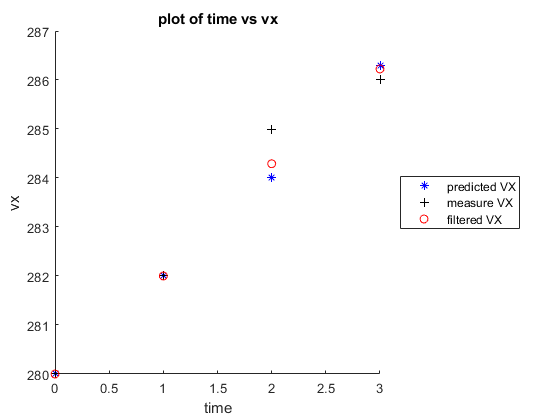


figure(2);
scatter(t,pred_V,'b', '*');
hold on;
scatter(t,measured_V,'k', '+');
hold on;
scatter(t,filt_V, 'r', 'o');
title("plot of time vs vx")
xlabel('time')
ylabel('vx')
legend('predicted VX','measure VX','filtered VX', 'Location', 'eastoutside')
hold off;